% TODO: По Нозлу можно решать fzero, либо с разделенными разностями Ньютона 
% (когда аналитически не посчитать производную). Для построения более 
% эффективного сопла используется метод характеристик. Часто используется 
% профиль Витошинского.

clc
close
clear

### **Практическая часть.**

Общие параметры.

TextSize = 15;
k_var = 1; % номер варианта

N = 100; % количество узлов 
k = 1.4; % показатель адиабаты

x0 = 0;
x_zv = 1;
x_a = 3;
r0 = 1.5;
r_zv = 1;
r_a = 2; % координаты точек, необходимые для построения контура сопла

p0 = 10 + 3 * k_var; % давление торможения (атм)
p0_converted = 101325.011 * p0; % давление торможения (Па)
T0 = 300; % температура газа в баллоне (K)

Построение контура сопла. Вывод на экран.

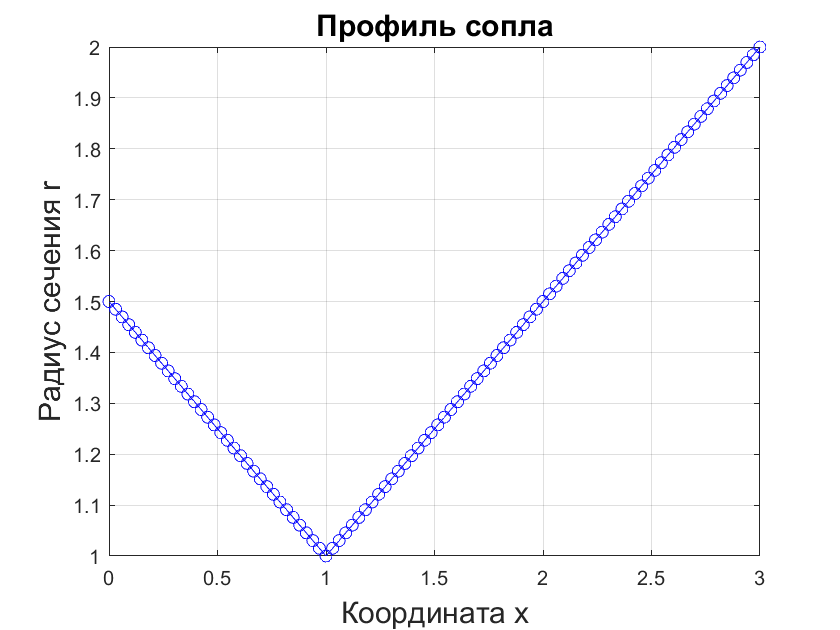

x = x0:(x_a - x0) / (N - 1):x_a;
cond = x < x_zv;
r =  (r0 + (r_zv - r0) / (x_zv - x0) * (x-x0)).*cond + ...
     (r_zv + (r_a - r_zv) / (x_a - x_zv) * (x - x_zv)).*(1 - cond);

figure(1);
plot(x, r, '-bo');
grid on;
title('Профиль сопла', 'FontSize', TextSize);
xlabel('Координата x', 'FontSize', TextSize);
ylabel('Радиус сечения r', 'FontSize', TextSize);

Параметры сопла.

F_zv = pi * r_zv^2; % площадь критического сечения
F = pi * r.^2; % площади всех сечений
q = F_zv./F; % функция приведенного расхода

Нахождение числа Маха и газодинамических характеристик.

M = zeros(1, N);
Pi = zeros(1, N);
Eps = zeros(1, N);
Tau = zeros(1, N);

for i=1:N
    
    if x(i) < 1
        
        M0 = 0.1; % начальное приближение в дозвуковой части
        
    else
        
        M0 = 1.5; % начальное приближение в сверхвуковой части
        
    end    
    
    M(i) = qSolveFun(q(i), k, M0);
    Pi(i) = (1 + ((k - 1) / 2) * M(i)^2)^(-k / (k - 1));
    Eps(i) = (1 + ((k - 1) / 2) * M(i)^2)^(-1 / (k - 1));   
    Tau(i) = (1 + ((k - 1) / 2) * M(i)^2)^(-1); % характеристики, вычисленные по формулам изоэнтропического течения
    
end

Построение графиков зависимостей газодинамических характеристик от координаты x.

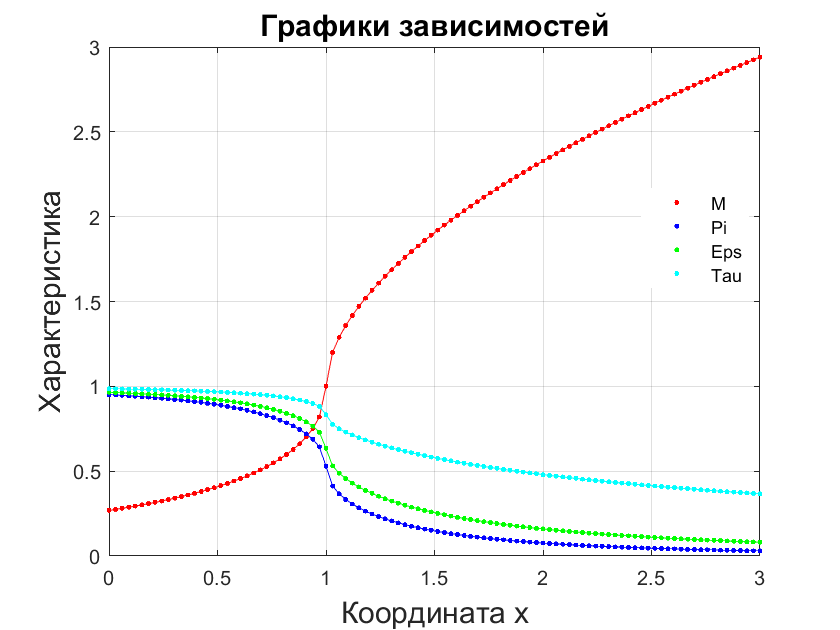

figure(2);
plot(x, M, '-r.');
title('Графики зависимостей', 'FontSize', TextSize);
xlabel('Координата x', 'FontSize', TextSize);
ylabel('Характеристика', 'FontSize', TextSize);
grid on;
hold on;
plot(x, Pi, '-b.');
plot(x, Eps, '-g.');
plot(x, Tau, '-c.');
hold off;
legend({'M', 'Pi', 'Eps', 'Tau'}, 'Location', 'best');

### **Исследовательская часть.**

Построение графиков распределений газодинамических параметров по соплу.

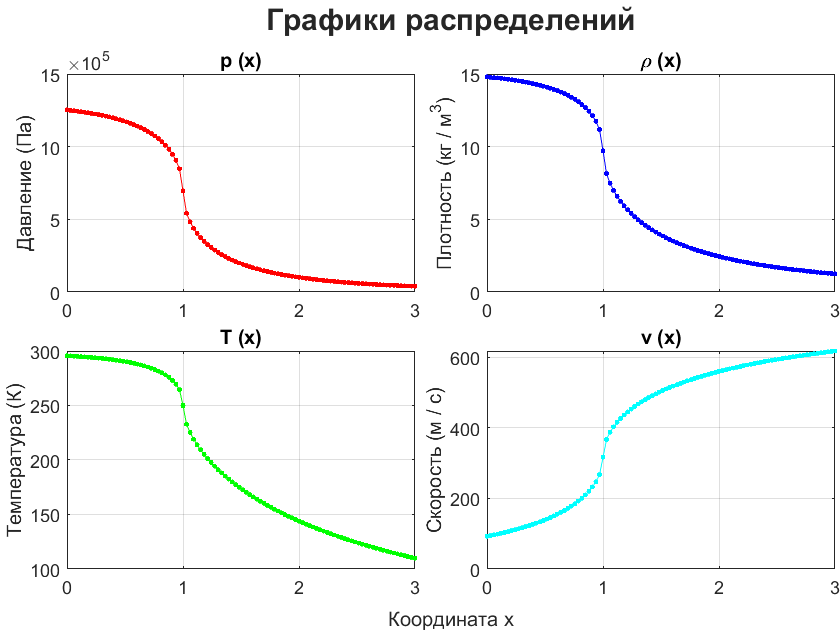

Mol = 0.029; % молярная масса воздуха (кг / моль)
R_gaz = 8.314; % универсальная газовая постоянная (Н * м / моль * К)

ro0 = 15.341; % плотность торможения воздуха (кг / м^3)
v_max = sqrt(2 * T0 * (k / (k - 1)) * R_gaz / Mol); % максимальная скорость истечения (м / с)

p = p0_converted.*Pi; % давление
rho = ro0.*Eps; % плотность
T = T0.*Tau; % температура
v = zeros(1, N); % скорость

for i = 1:N
    
    v(i) = v_max * (((k - 1) / 2) * M(i)^2 / (1 + (((k - 1) / 2) * M(i)^2)))^(1 / 2);
    
end

figure(3);
tl = tiledlayout(2,2);
tl.TileSpacing = 'none';
tl.Padding = 'none';

ax1 = nexttile;
plot(ax1, x, p, '-r.');
title('p (x)', 'FontSize', TextSize);
ylabel('Давление (Па)', 'FontSize', TextSize-5);
grid on;

ax2 = nexttile;
plot(ax2, x, rho, '-b.');
title('\rho (x)', 'FontSize', TextSize);
ylabel('Плотность (кг / м^3)', 'FontSize', TextSize-5);
grid on;

ax3 = nexttile;
plot(ax3, x, T, '-g.');
title('T (x)', 'FontSize', TextSize);
ylabel('Температура (К)', 'FontSize', TextSize-5);
grid on;

ax4 = nexttile;
plot(ax4, x, v, '-c.');
title('v (x)', 'FontSize', TextSize);
ylabel('Скорость (м / с)', 'FontSize', TextSize-5);
grid on;

linkaxes([ax1, ax2, ax3, ax4], 'x');
title(tl, 'Графики распределений', 'FontWeight', 'bold', 'FontSize', TextSize)
xlabel(tl, 'Координата x', 'FontSize', TextSize-5);

Нахождение числа нерасчетности истечения и геометрического числа Маха сопла.

p_atm = 101325; % нормальное атмосферное давление (Па)

n = p(N) / p_atm;
fprintf('Число нерасчетности истечения: %f. Течение является безотрывным.', n);

Число нерасчетности истечения: 0.387231. Течение является безотрывным.

M_a = M(N);
fprintf('Геометрическое число Маха сопла: %f.', M_a);

Геометрическое число Маха сопла: 2.940179.